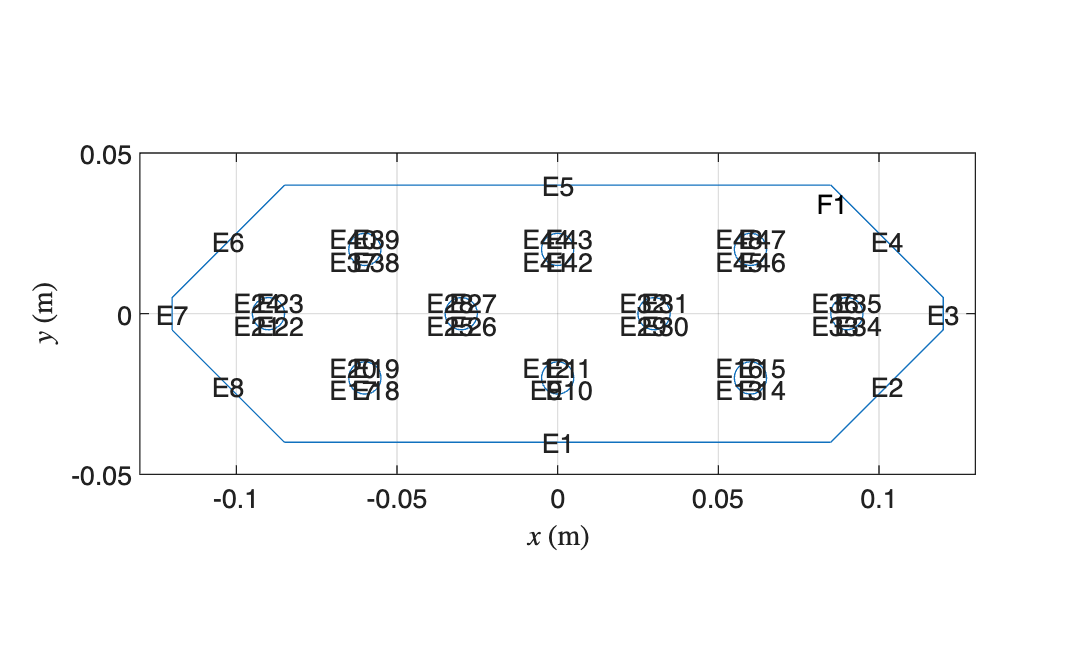

clc
close all;
clear

model = createpde("thermal","steadystate");


R_w = 0.01;
C_R = R_w/2;

t = 0.001;

h = 80;
T_inf = 30;
T_tube = 60;
k = 180;


C1=[1;0;-R_w*2;C_R;0;0;0;0;0;0];
C2=[1;6*R_w;-R_w*2;C_R;0;0;0;0;0;0];
C3=[1;-6*R_w;-R_w*2;C_R;0;0;0;0;0;0];

C4=[1;-9*R_w;0;C_R;0;0;0;0;0;0];
C5=[1;-3*R_w;0;C_R;0;0;0;0;0;0];
C6=[1;3*R_w;0;C_R;0;0;0;0;0;0];
C7=[1;9*R_w;0;C_R;0;0;0;0;0;0];

C8=[1;-6*R_w;R_w*2;C_R;0;0;0;0;0;0];
C9=[1;0;R_w*2;C_R;0;0;0;0;0;0];
C10=[1;6*R_w;R_w*2;C_R;0;0;0;0;0;0];


cut = 3.5*R_w;

P = [2;8; ...


    -12*R_w + cut;
     12*R_w - cut;
     12*R_w;
     12*R_w;
     12*R_w - cut;
    -12*R_w + cut;
    -12*R_w;
    -12*R_w;


    -4*R_w;
    -4*R_w;
    -4*R_w + cut;
     4*R_w - cut;
     4*R_w;
     4*R_w;
     4*R_w - cut;
    -4*R_w + cut];

gd = [P,...
      [C1;zeros(8,1)],...
      [C2;zeros(8,1)],...
      [C3;zeros(8,1)],...
      [C4;zeros(8,1)],...
      [C5;zeros(8,1)],...
      [C6;zeros(8,1)],...
      [C7;zeros(8,1)],...
      [C8;zeros(8,1)],...
      [C9;zeros(8,1)],...
      [C10;zeros(8,1)]];

ns = char('P','C1','C2','C3','C4','C5','C6','C7','C8','C9','C10')';

sf = 'P-C1-C2-C3-C4-C5-C6-C7-C8-C9-C10';

[dl,bt] = decsg(gd,sf,ns);
[dl2,bt2] = csgdel(dl,bt);

geometryFromEdges(model,dl2);




figure
pdegplot(model,EdgeLabels="on",FaceLabels="on")

axis equal
xlim([-0.13 0.13])
ylim([-0.05 0.05])

xlabel('$x$ (m)','Interpreter','latex')
ylabel('$y$ (m)','Interpreter','latex')

grid on
box on

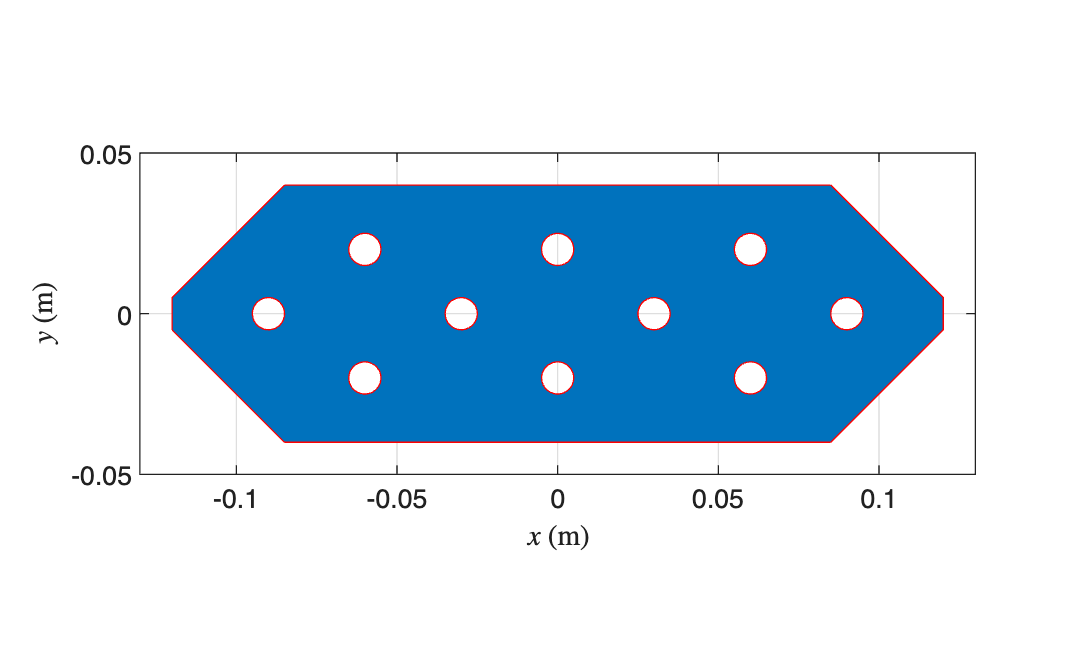





Hmax = 0.0004 ;

mesh = generateMesh(model,'Hmax',Hmax);

figure
pdeplot(mesh)

axis equal
xlim([-0.13 0.13])
ylim([-0.05 0.05])

xlabel('$x$ (m)','Interpreter','latex')
ylabel('$y$ (m)','Interpreter','latex')

grid on
box on

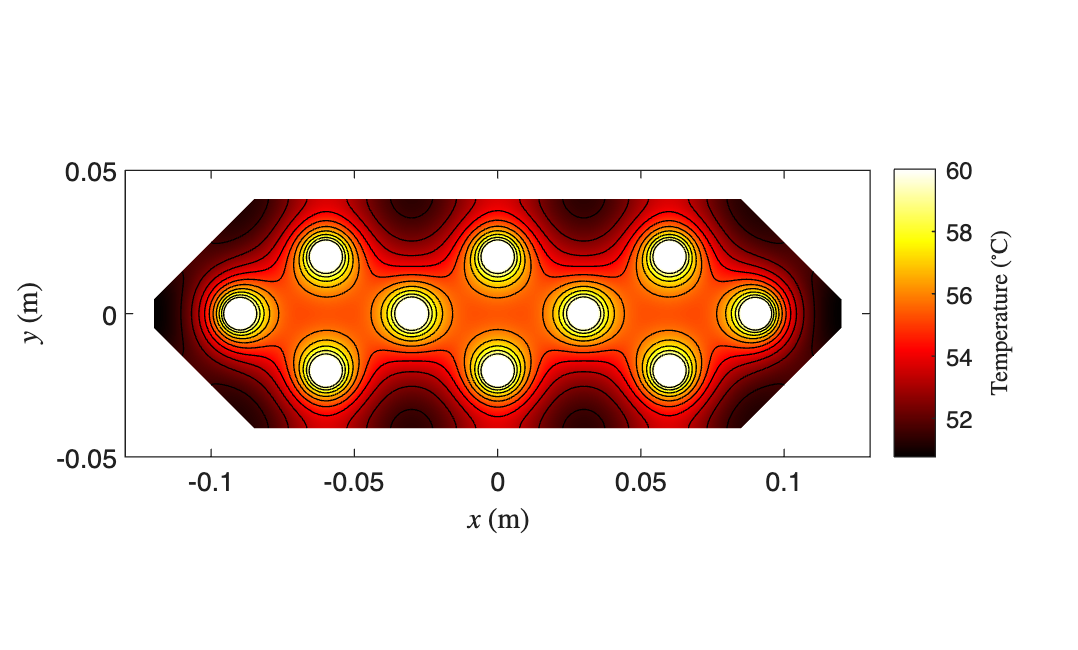





outerEdges = 1:8;
tubeEdges = 8:48;




thermalBC(model,'Edge',tubeEdges, ...
    'Temperature',T_tube);

thermalBC(model,'Edge',outerEdges, ...
    'ConvectionCoefficient',h, ...
    'AmbientTemperature',T_inf);

thermalProperties(model, ...
    'ThermalConductivity',k);




internalHeatSource(model, ...
    @(region,state) -(2*h/t)*(state.u-T_inf));




result = solve(model);

T=result.Temperature;




figure
pdeplot(model,'XYData',T, ...
    "Contour","on", ...
    "ColorMap",'hot')

axis equal
xlim([-0.13 0.13])
ylim([-0.05 0.05])

xlabel('$x$ (m)','Interpreter','latex')
ylabel('$y$ (m)','Interpreter','latex')

cb = colorbar;
cb.Label.String = 'Temperature ($^\circ$C)';
cb.Label.Interpreter = 'latex';

box on





Q_per_m = 0;

for e = tubeEdges
    Q_per_m = Q_per_m + ...
        evaluateHeatRate(result,'Edge',e);
end


Q_fin = abs(Q_per_m)*t;


L_plate = 24*R_w;
W_plate = 8*R_w;


A_cut = 4*(0.5*cut^2);


A_faces = 2*(L_plate*W_plate - A_cut - 10*pi*C_R^2);


Perimeter = 2*(L_plate+W_plate) ...
          - 8*cut ...
          + 4*sqrt(2)*cut;

A_outer_edge = Perimeter*t;

A_fin = A_faces + A_outer_edge;




Q_max = h*A_fin*(T_tube-T_inf);




eta_fin = Q_fin/Q_max;


fprintf('Minimum temperature    = %.2f degC\n',min(T))

Minimum temperature    = 50.77 degC


fprintf('Maximum temperature    = %.2f degC\n',max(T))

Maximum temperature    = 60.00 degC


fprintf('Heat transfer from fin = %.2f W\n',Q_fin)

Heat transfer from fin = 63.19 W


fprintf('Maximum heat transfer = %.2f W\n',Q_max)

Maximum heat transfer = 77.97 W


fprintf('Fin efficiency         = %.2f %%\n',100*eta_fin)

Fin efficiency         = 81.04 %
